# Deel 1 practicum regeltechniek 

Auteur: Perijn Huijser

**Datum: 25-09-2025**

## Changelog

Versie 1.0 - 25-09-2025

-Initiale opbouw

## Opdracht 2.2 - Stapresponsies

### Opdracht 2.2.1

Defineer laplace 's' variable

clear
close all;
s=tf('s');

Defineer de processen

proc_a = (6 / (s + 4));
proc_b = ((3*s + 4) / (s^2 + 6*s + 8) );
proc_c = ((2*s + 1) / (4*s^2 + 16*s + 32));

Plot de step responsies

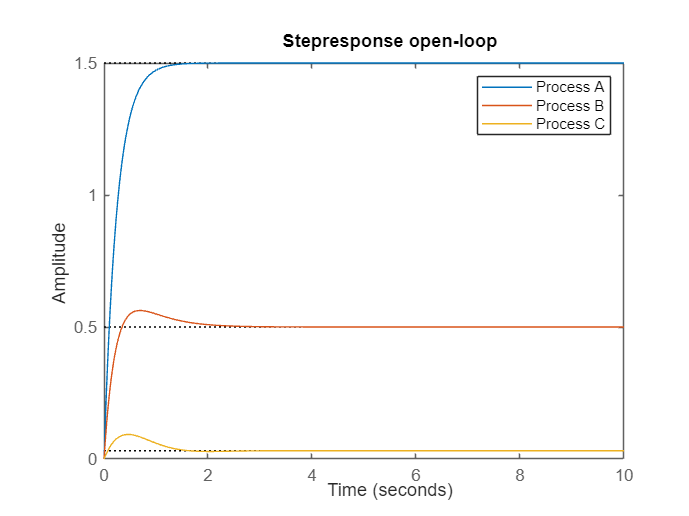

% Create one plot figure
figure;
hold on;
grid on;

step(proc_a, 10)
step(proc_b, 10)
step(proc_c, 10)

hold off
legend("Process A", "Process B", "Process C");
title('Stepresponse open-loop');

### Opdracht 2.2.2 - Stapresponsie closed-loop

defineer closed loop systemen

ClosedLoopA = ClosedLoopStep(proc_a);
ClosedLoopB = ClosedLoopStep(proc_b);
ClosedLoopC = ClosedLoopStep(proc_c);

Defineer 'k' variablen

K1 = 1;
K2 = 10;
K3 = 100;

Process A

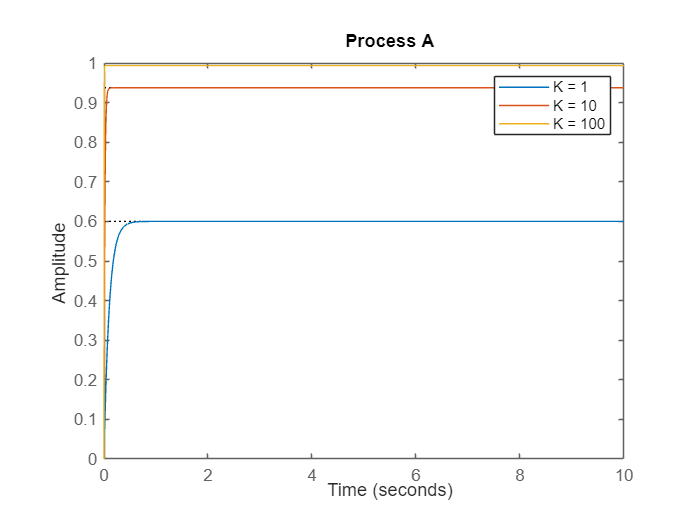

figure;
hold on;
step(ClosedLoopA(K1), 10)
step(ClosedLoopA(K2), 10)
step(ClosedLoopA(K3), 10)
hold off;
legend("K = 1", "K = 10", "K = 100")
title("Process A");

Process B

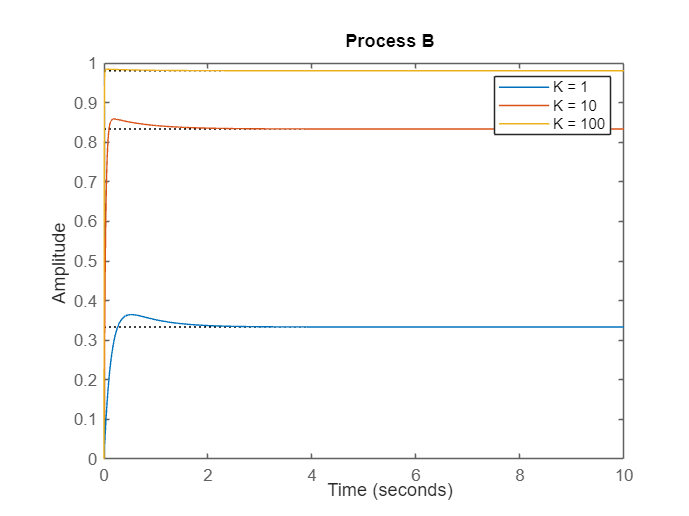

figure;
hold on;
step(ClosedLoopB(K1), 10)
step(ClosedLoopB(K2), 10)
step(ClosedLoopB(K3), 10)
hold off;
legend("K = 1", "K = 10", "K = 100")
title("Process B");

Process C

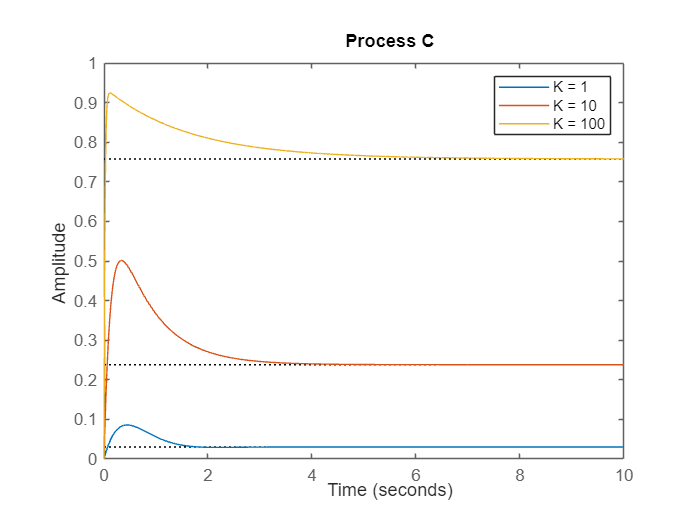

figure;
hold on;
step(ClosedLoopC(K1), 10)
step(ClosedLoopC(K2), 10)
step(ClosedLoopC(K3), 10)
hold off;
legend("K = 1", "K = 10", "K = 100")
title("Process C");

## Opdracht 2.3 Bode diagram en polen- en nulpuntenbeeld

clear

s=tf('s');

Defineer processen

H1 = 1 / ((s+2) * (s+1));
H2 = 1/ ((2*s + 1) * (0.01*s + 1)^2);
H3 = (s^2+6*s+13)/(s^3+0.2*s^2+s);

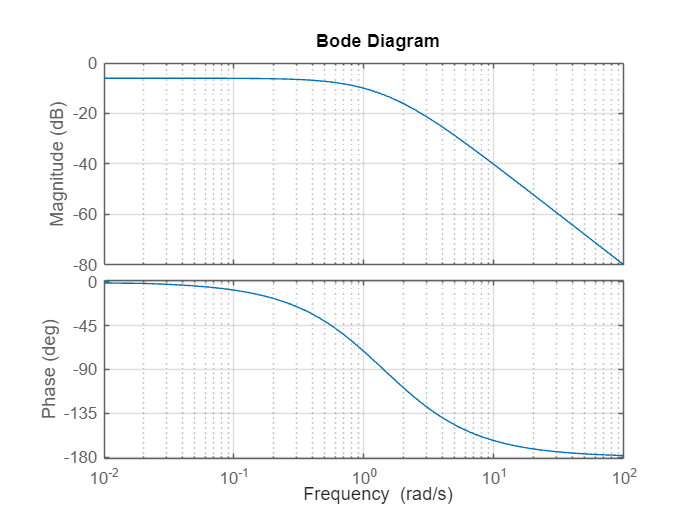

bode(H1)
grid on;

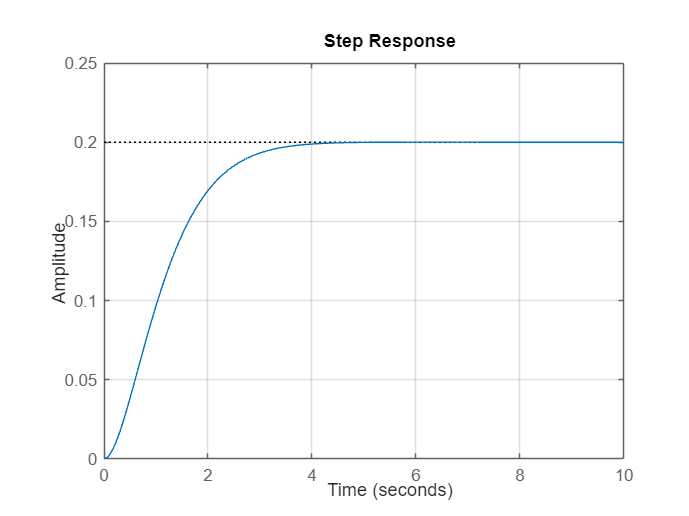


K = 0.5;
trans = ClosedLoopStep(H1);

figure;
step(trans(K), 10);
grid on;

stepinfo(trans(K))

ans = struct with fields:
         RiseTime: 1.9661
    TransientTime: 3.3179
     SettlingTime: 3.3179
      SettlingMin: 0.1801
      SettlingMax: 0.2000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2000
         PeakTime: 5.4955




HL1 = 1/ ((10e-5*s^2) + (20*s) + (1/1e-9))

HL1 =
 
             1
  ------------------------
  0.0001 s^2 + 20 s + 1e09
 
Continuous-time transfer function.
Model Properties



pole(H1)

ans =     -2
    -1


dcgain(H1)

ans = 0.5000


ss(HL1)

ans =
 
  A = 
               x1          x2
   x1      -2e+05  -2.384e+06
   x2   4.194e+06           0
 
  B = 
           u1
   x1  0.0625
   x2       0
 
  C = 
            x1       x2
   y1        0  0.03815
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


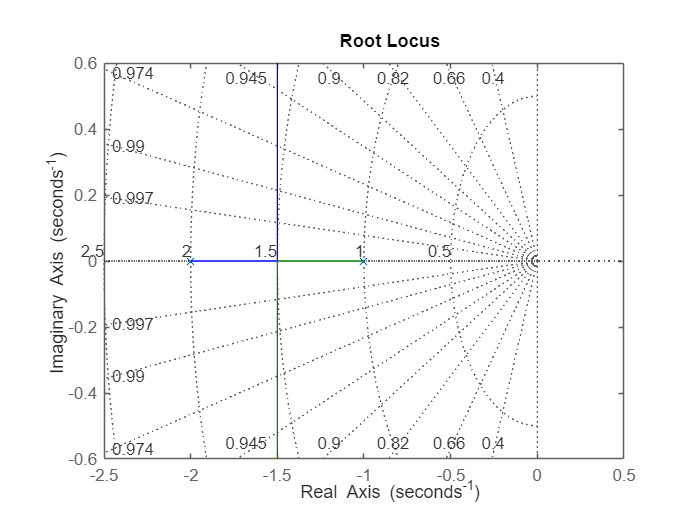


[r, k] = rlocus(H1);
rlocus(H1)
grid on;

## Helper functies

### Closed-loop step

function transfer = ClosedLoopStep(Process)
    ol = @(k) series(k,Process);
    back = 1;

    transfer = @(n) feedback(ol(n),back);
end